# Power-Split Hybrid Electric Vehicle Model with Direct Input

## MG1 Starts, Drives, and Stops Vehicle

Reverse rotation of MG1 can drive the axle. This is possible because sprag clutch attached to engine crank prevents the crank from spinning in the negative direction.

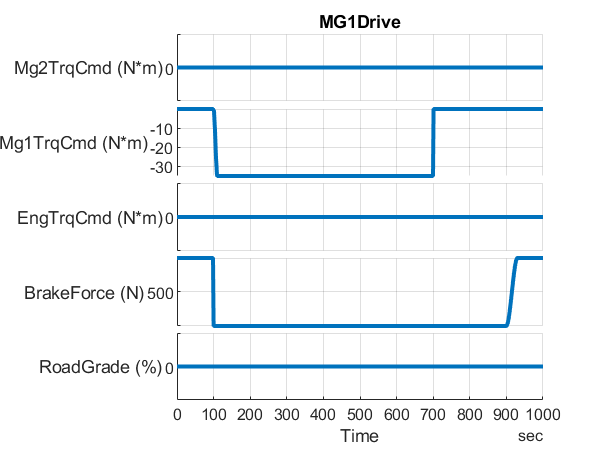

mdl = "PowerSplitHEV_system_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitHEV_params

set_param(mdl+"/Controller & Environment", ...
  ReferencedSubsystem = "PowerSplitHEV_DirectInput_refsub");

builder = PowerSplitHEV_DirectInput_InputSignalBuilder;
builder.Plot_tf = true;

hevDirectInputData = MG1Drive(builder);


% Load data in the base workspace.
% This allows the Run button to work.
hevDirect_InputSignals = hevDirectInputData.Signals;
hevDirect_InputBus = hevDirectInputData.Bus;
t_end = hevDirectInputData.Options.StopTime_s;

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime", num2str(t_end));
simIn = setVariable(simIn, "hevDirect_InputSignals", hevDirect_InputSignals);
simIn = setVariable(simIn, "hevDirect_InputBus", hevDirect_InputBus);

simOut = sim(simIn);

['PowerSplitHEV_system_model/Solver Configuration/Solver Configuration']: At time 687.669462, one or more assertions are triggered. See causes
for specific information.

Caused by:
    Error using Simulink.Simulation.internal.DesktopSimHelper>@(simIn)builtin('sim',simIn)
    Input current must be less than Maximum expected supply-side current. The assertion comes from:
    Block path: PowerSplitHEV_system_model/DC-DC Converter/DC-DC Converter
    Assert location:
        o (location information is protected)


fig = figure;
PowerSplitHEV_plot_result_compact( "Dataset",simOut.logsout, "PlotParent",fig );
fig = figure;
PowerSplitHEV_plot_result_vehicle( "Dataset",simOut.logsout, "PlotParent",fig );
fig = figure;
PowerSplitHEV_plot_result_hvbattery( "Dataset",simOut.logsout, "PlotParent",fig );
fig = figure;
PowerSplitHEV_plot_result_powersplit( "Dataset",simOut.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*